% a
Xjw = 1 ./ (2 + j * w) + 1 ./ (2 - j * w);

错误使用  / 
矩阵维度必须一致。

% b
tau = 0.01;
T = 10;
t = 0 : tau : T-tau;
t1 = 0 : tau : T - 5 - tau;
t2 = T - 5 : tau : T - tau;
% x = exp(2 .* t);
y = [exp(-2 .* t1), exp(2 .* t2)];

plot(t, y);
xlabel("t");
ylabel("y(t)");

N = T / tau;

% c
Y = fftshift(tau * fft(y));

% d
w = -(pi / tau) + (0 : N - 1) * (2 * pi / (N * tau));

% e
X = Y .* exp(j * 5 .* w);

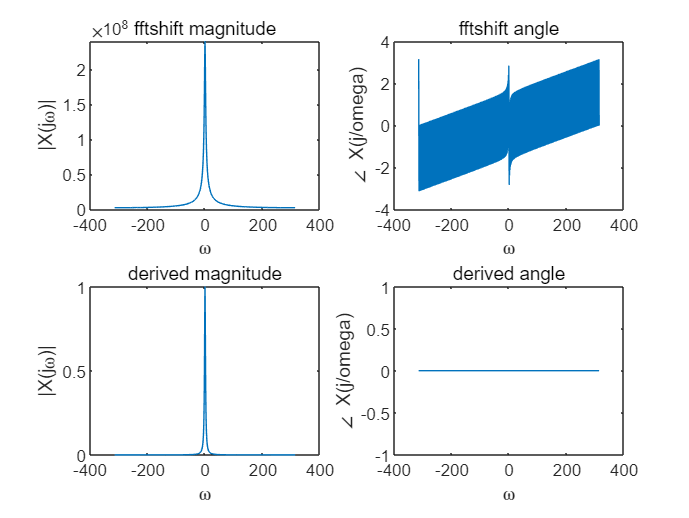

% f
subplot(2, 2, 1);
plot(w, abs(X));
xlabel("\omega");
ylabel("|X(j\omega)|");
title("fftshift magnitude")
subplot(2, 2, 2);
plot(w, angle(X));
xlabel("\omega");
ylabel("\angle X(j/omega)");
title("fftshift angle")

Xjw = (2 - j * w) ./ (4 + w.^2) + (2 + j * w) ./ (4 + w.^2);
subplot(2, 2, 3);
plot(w, abs(Xjw));
xlabel("\omega");
ylabel("|X(j\omega)|");
title("derived magnitude")
subplot(2, 2, 4);
plot(w, angle(Xjw));
xlabel("\omega");
ylabel("\angle X(j/omega)");
title("derived angle")

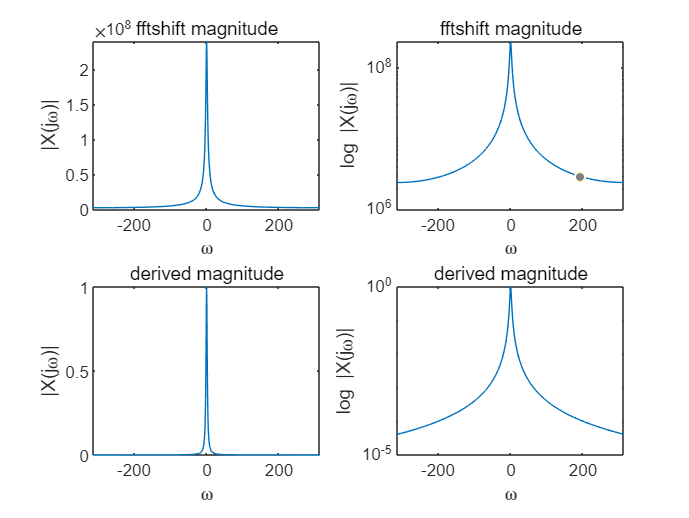


close all;
subplot(2, 2, 1);
plot(w, abs(X));
xlabel("\omega");
ylabel("|X(j\omega)|");
title("fftshift magnitude")
subplot(2, 2, 2);
semilogy(w, abs(X));
xlabel("\omega");
ylabel("log |X(j\omega)|");
title("fftshift magnitude")

subplot(2, 2, 3);
plot(w, abs(Xjw));
xlabel("\omega");
ylabel("|X(j\omega)|");
title("derived magnitude")
subplot(2, 2, 4);
semilogy(w, abs(Xjw));
xlabel("\omega");
ylabel("log |X(j\omega)|");
title("derived magnitude")

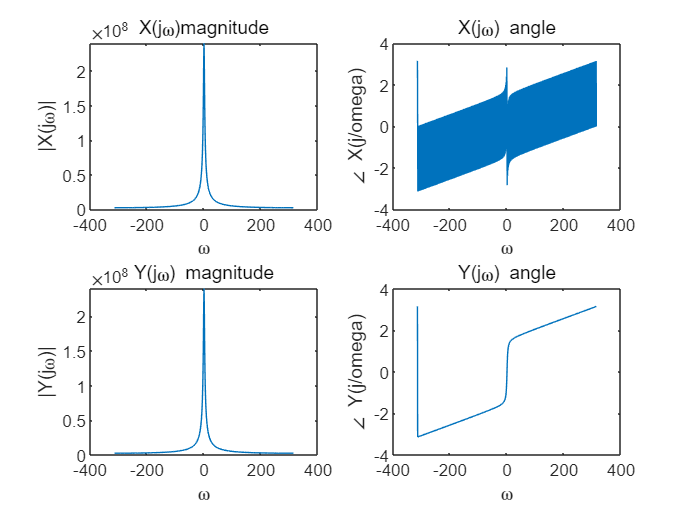

% g
subplot(2, 2, 1);
plot(w, abs(X));
xlabel("\omega");
ylabel("|X(j\omega)|");
title("X(j\omega)magnitude")
subplot(2, 2, 2);
plot(w, angle(X));
xlabel("\omega");
ylabel("\angle X(j/omega)");
title("X(j\omega) angle")

subplot(2, 2, 3);
plot(w, abs(Y));
xlabel("\omega");
ylabel("|Y(j\omega)|");
title("Y(j\omega) magnitude")
subplot(2, 2, 4);
plot(w, angle(Y));
xlabel("\omega");
ylabel("\angle Y(j/omega)");
title("Y(j\omega) angle")